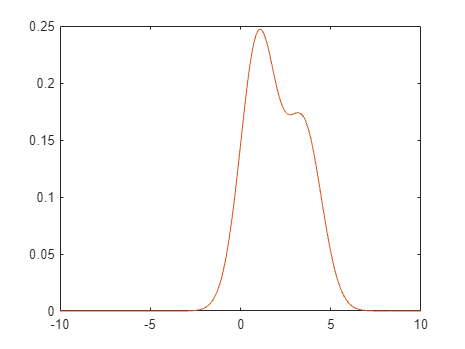

clear, clc, close all;

load('x.mat')
load('y.mat')
nbins = 50;
plot(x,y)
hold on;
% histogram(y,nbins)
x_est = linspace(-10,10,2001);
mu1 = 1.0; % For larger peak
mu2 = 3.5; % For smaller peak
variance1 = 1;
variance2 = 1;
alpha = 0.6;
y_est = alpha*normpdf(x_est,mu1,variance1) + (1-alpha)*normpdf(x_est,mu2,variance2);
plot(x_est,y_est)
hold off;

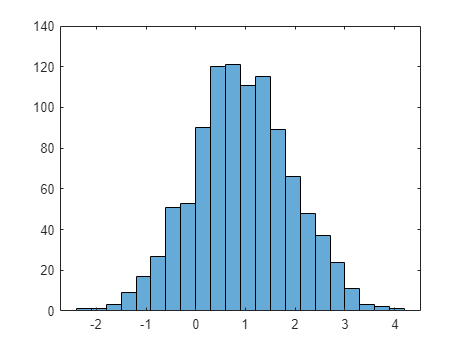


my_mu = 1;
my_variance = 1;
my_x = my_mu + sqrt(my_variance)*randn(1000,1);
histogram(my_x)

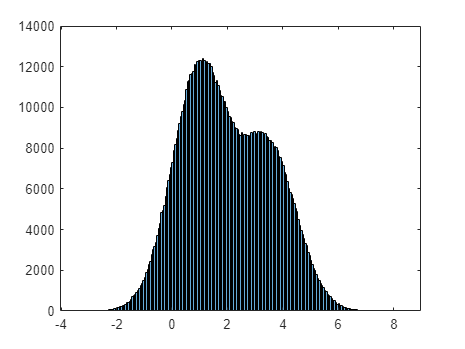


N = 1e6;
x_new = zeros(N,1);
for k=1:N
    temp = rand;
    if temp < alpha
        x_new(k) = mu1 + sqrt(variance1)*randn;
    else
        x_new(k) = mu2 + sqrt(variance2)*randn;
    end
end
histogram(x_new)

clc, clear, close all;

